# Model Failed Elements

clc;
close all;
clear variables
rng(123);

## Assign constants

fc = 60e9;
c = physconst("LightSpeed");
lmd = freq2wavelen(fc);
ele = phased.CosineAntennaElement;

## Update fail probability

failProb = 0.2;
ura = phased.URA("Element", ele, "ElementSpacing", lmd/2, "Size", [16, 16]);
ura_failed = phased.URA("Element", ele, "ElementSpacing", lmd/2, "Size", [16, 16] ...
    , "Taper", double(rand(16,16) > failProb));

## Visualize array geometry

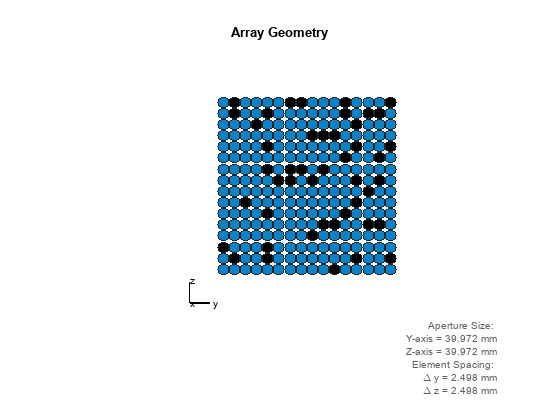

ura_failed.viewArray("ShowTaper", true)

## Visualize antenna patterns

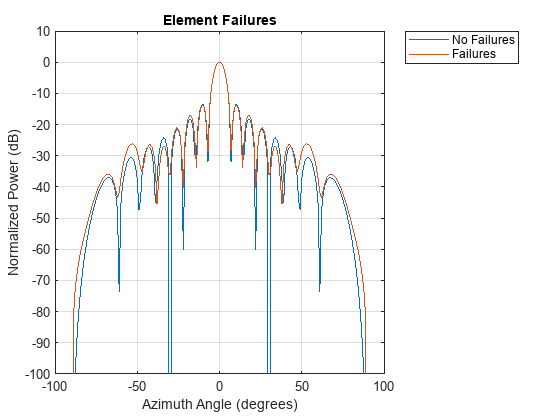

figure;
ura.pattern(60e9, -180:180,0, "Type", "powerdb", "CoordinateSystem", "rectangular", "PropagationSpeed", c)
hold on;
ura_failed.pattern(60e9, -180:180,0, "Type", "powerdb", "CoordinateSystem", "rectangular", "PropagationSpeed", c)
legend(["No Failures", "Failures"])
title("Element Failures")